clear;
simIn = Simulink.SimulationInput('noiseModel');

n = 10;
newPointCloud = [NaN, NaN];

for i = 1:n
    simOut = sim(simIn);
    newPointCloud = [newPointCloud; [simOut.tout, simOut.yout]];
end
newPointCloud = newPointCloud(2:end, :);

load pointCloud.mat
fullPointCloud = [fullPointCloud; newPointCloud];
save('pointCloud.mat');

pointCloud = fullPointCloud(randi(length(fullPointCloud), 1e2, 1), :);
% pointCloud = fullPointCloud(1:6000:600000, :);
timeList = pointCloud(:, 1);
[timeList, ind] = sort(timeList, 'ascend');
xList = pointCloud(ind, 2);
[timeGrid, xGrid] = ndgrid(timeList, xList);
freqGrid = zeros(size(timeGrid));

for i = 1:size(timeGrid, 1)
    for j = 1:size(timeGrid, 2)
        freqGrid(i, j) = sum((timeList <= timeGrid(i, j)) & (xList <= xGrid(i, j)), 'all');
    end
end
freqGrid = freqGrid / length(pointCloud);

pdfGrid = zeros(size(freqGrid));
stds = zeros(size(timeGrid, 1), 1);
for i = 1:size(timeGrid, 1)
    [sortedX, ind] = sort(xGrid(i, :), 'ascend');
    pdfGrid(i, :) = gradient(freqGrid(i, ind))./gradient(sortedX);
    stds(i) = std(sortedX);
end

% F = griddedInterpolant(timeGrid, xGrid, freqGrid);
% numFinePoints = 1e3;
% fineTimeList = linspace(timeList(1), timeList(end), numFinePoints);
% fineXList = linspace(min(xList), max(xList), numFinePoints);
% [fineTimeGrid, fineXGrid] = ndgrid(fineTimeList, fineXList);
% fineFreqGrid = F(fineTimeGrid, fineXGrid);

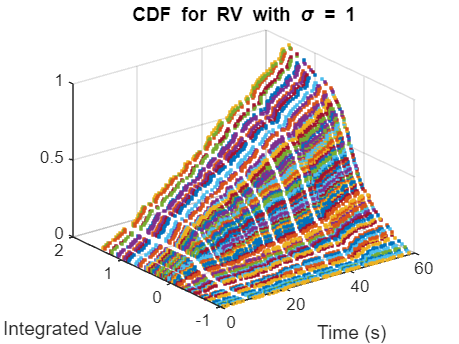

figure;
scatter3(timeGrid, xGrid, freqGrid, '.');
xlabel("Time (s)");
ylabel("Integrated Value");
title("CDF for RV with \sigma = 1")

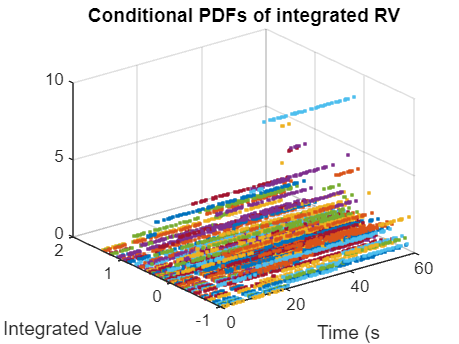


figure;
scatter3(timeGrid, xGrid, pdfGrid, '.');
xlabel("Time (s");
ylabel("Integrated Value");
title("Conditional PDFs of integrated RV");

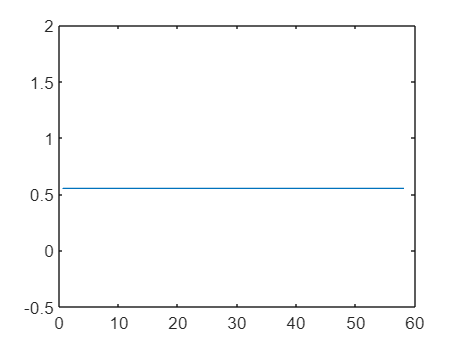


figure;
plot(timeList, stds);